% 4CBLA30 EST modeling

% Import/exstract data supply
data_supply = readmatrix("Team62_supply.csv","NumHeaderLines", 4);
time_supply_seconds = data_supply(:,1);
power_supply = data_supply(:,2);

% Import/exstract data demand
data_demand = readmatrix("Team62_demand.csv", "NumHeaderLines", 4);
time_demand_seconds = data_demand(:,1);
power_demand = data_demand(:,2);


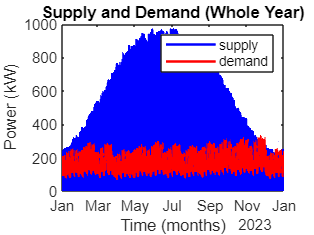

% Change the time to months
start_date = datetime(2023, 1, 1); 
time_supply_datetime = start_date + seconds(time_supply_seconds);
time_demand_datetime = start_date + seconds(time_demand_seconds);

% Plot with supply and demand for the whole year
plot(time_supply_datetime, power_supply, "b", 'LineWidth', 1.5);
hold on;
plot(time_demand_datetime, power_demand, "r", 'LineWidth', 1.5);

xlabel("Time (months)");
ylabel("Power (kW)");
title("Supply and Demand (Whole Year)");
legend("supply","demand");


% Conclusions about graph of the whole year
%
% The supply/demand is measured over the timespan of a year
% Too much energy is generated compared to the engery demand
% In December there are multiple times where there is more demand then supply


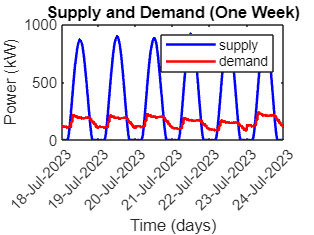

% Define the start and end date for the week
start_week = datetime(2023, 07, 18); 
end_week = datetime(2023, 07, 24); 

% Filter data for one week
index_supply_w = time_supply_datetime >= start_week & time_supply_datetime <= end_week;
time_supply_week = time_supply_datetime(index_supply_w);
power_supply_week = power_supply(index_supply_w);

index_demand_w = time_demand_datetime >= start_week & time_demand_datetime <= end_week;
time_demand_week = time_demand_datetime(index_demand_w);
power_demand_week = power_demand(index_demand_w);

% Plot with supply and demand for one week
plot(time_supply_week, power_supply_week, "b", "LineWidth", 1.5); 
hold on; 
plot(time_demand_week, power_demand_week, "r", "LineWidth", 1.5);

xlim([start_week, end_week]);
datetick("x", "dd-mmm-yyyy", "keepticks");

xlabel("Time (days)");
ylabel("Power (kW)");
title("Supply and Demand (One Week)");
legend("supply", "demand");


% Conclusions about graph of one week
%
% change the start_week and end_week date to see the supply and demand for
% different weeks

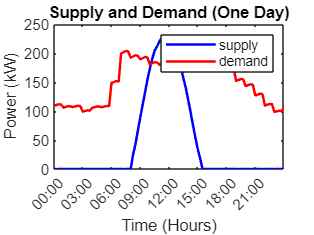

% Define the start and end time for the day
start_day = datetime(2023, 01, 01, 0, 0, 0); 
end_day = datetime(2023, 01, 01, 23, 59, 59); 

% Filter data for one day
index_supply_d = time_supply_datetime >= start_day & time_supply_datetime <= end_day;
time_supply_day = time_supply_datetime(index_supply_d);
power_supply_day = power_supply(index_supply_d);

index_demand_d = time_demand_datetime >= start_day & time_demand_datetime <= end_day;
time_demand_day = time_demand_datetime(index_demand_d);
power_demand_day = power_demand(index_demand_d);

% Plot with supply and demand for one day
plot(time_supply_day, power_supply_day, "b", "LineWidth", 1.5); 
hold on; 
plot(time_demand_day, power_demand_day, "r",  "LineWidth", 1.5); 

xlim([start_day, end_day]);
datetick("x", "HH:00", "keeplimits");

xlabel("Time (Hours)");
ylabel("Power (kW)");
title("Supply and Demand (One Day)");
legend("supply", "demand");


% Conclusions about graph of one day
%
% change the start_day and end_day date (only the month and day) to see the supply and demand for
% different days

%calculate the area between the blue and red graph when the blue graph is
%above the red graph

% Find segments where the blue graph is above the red graph
above_segment_excess = power_supply > power_demand;

% Initialize variables to store total area
total_area_excess = 0;

% Iterate through each segment
for i = 1:length(above_segment_excess)-1
    if above_segment_excess(i)
        % Calculate the area under the blue graph within the segment
        area_blue_excess = trapz(time_supply_seconds(i:i+1), power_supply(i:i+1));

        % Calculate the area under the red graph within the segment
        area_red_excess = trapz(time_demand_seconds(i:i+1), power_demand(i:i+1));

        % Subtract the area under the red graph from the area under the blue graph
        area_diff_excess = area_blue_excess - area_red_excess;
        
        % Add the area difference to the total area
        total_area_excess = total_area_excess + area_diff_excess;
    end
end

%print the total area to the screen
disp('Total area between the blue and red graphs when blue is above red:')

Total area between the blue and red graphs when blue is above red:


disp(total_area_excess);

   3.4902e+09



%calculate the area between the red and blue graph when the red graph is
%above the blue graph

% Find segments where the red graph is above the blue graph
above_segment_needed = power_demand > power_supply;

% Initialize variables to store total area
total_area_needed = 0;

% Iterate through each segment
for i = 1:length(above_segment_needed)-1
    if above_segment_needed(i)
        % Calculate the area under the red graph within the segment
        area_red_needed = trapz(time_demand_seconds(i:i+1), power_demand(i:i+1));

        % Calculate the area under the blue graph within the segment
        area_blue_needed = trapz(time_supply_seconds(i:i+1), power_supply(i:i+1));

        % Subtract the area under the red graph from the area under the blue graph
        area_diff_needed = area_red_needed - area_blue_needed;
        
        % Add the area difference to the total area
        total_area_needed = total_area_needed + area_diff_needed;
    end
end

%print the total area to the screen
disp('Total area between the red and blue graphs when red is above blue:');

Total area between the red and blue graphs when red is above blue:


disp(total_area_needed);

   2.8594e+09




%calculate the difference in supply surplus and the demand deficit
difference_sup_dem = total_area_excess - total_area_needed;
disp('This is the difference between the supply surplus and the demand deficit');

This is the difference between the supply surplus and the demand deficit


disp(difference_sup_dem);

   6.3082e+08



%calculate the area between the blue and red graph per day when the blue graph is
%above the red graph

% Find segments where the blue graph is above the red graph
above_segment_excess_day = power_supply > power_demand;

% change time from datetime back to seconds
time_supply_seconds_day = seconds(time_supply_day - start_date);
time_demand_seconds_day = seconds(time_demand_day - start_date);

% Initialize variables to store total area
total_area_excess_day = 0;

% Iterate through each segment
for i = 1:length(above_segment_excess_day)-1
    if above_segment_excess_day(i)
        % Calculate the area under the blue graph within the segment
        area_blue_excess_day = trapz(time_supply_seconds(i:i+1), power_supply_day(i:i+1));

        % Calculate the area under the red graph within the segment
        area_red_excess_day = trapz(time_demand_seconds(i:i+1), power_demand_day(i:i+1));

        % Subtract the area under the red graph from the area under the blue graph
        area_diff_excess_day = area_blue_excess_day - area_red_excess_day;
        
        % Add the area difference to the total area
        total_area_excess_day = total_area_excess_day + area_diff_excess_day;
    end
end

Index exceeds the number of array elements. Index must not exceed 96.


%print the total area to the screen
disp('Total area between the blue and red graphs per day when blue is above red:')
disp(total_area_excess);